# Finding a 4D SSM from resonant vibration data

We analyze the dynamics along a slow 4D resonant SSM. This example uses velocity measurements from laser scanner vibrometry [1].

clearvars
close all
format shortg
clc

[1] M. Cenedese, J. Axås, H. Yang, M. Eriten & G. Haller, Data-driven nonlinear model reduction to spectral  submanifolds in mechanical systems, [*Philosophical Transactions of the Royal Society A: Mathematical, Physical and Engineering Sciences*](https://doi.org/10.1098/rsta.2021.0194) 380, 20210194 (2022). [[PDF]](https://arxiv.org/pdf/2110.01929) 

## Example setup

The data consists of 12 decaying velocity signals measured on the tip of the inner beam, excited via hammer impacts. These occur on three positions (4 repetitions per impact) along the inner beam, spaced from the joint to the free end. An initial data inspection reveal two fundamental resonant frequencies, hereby justifying the identification of the slow 4D SSM of the system. Additional information can be found in [1].

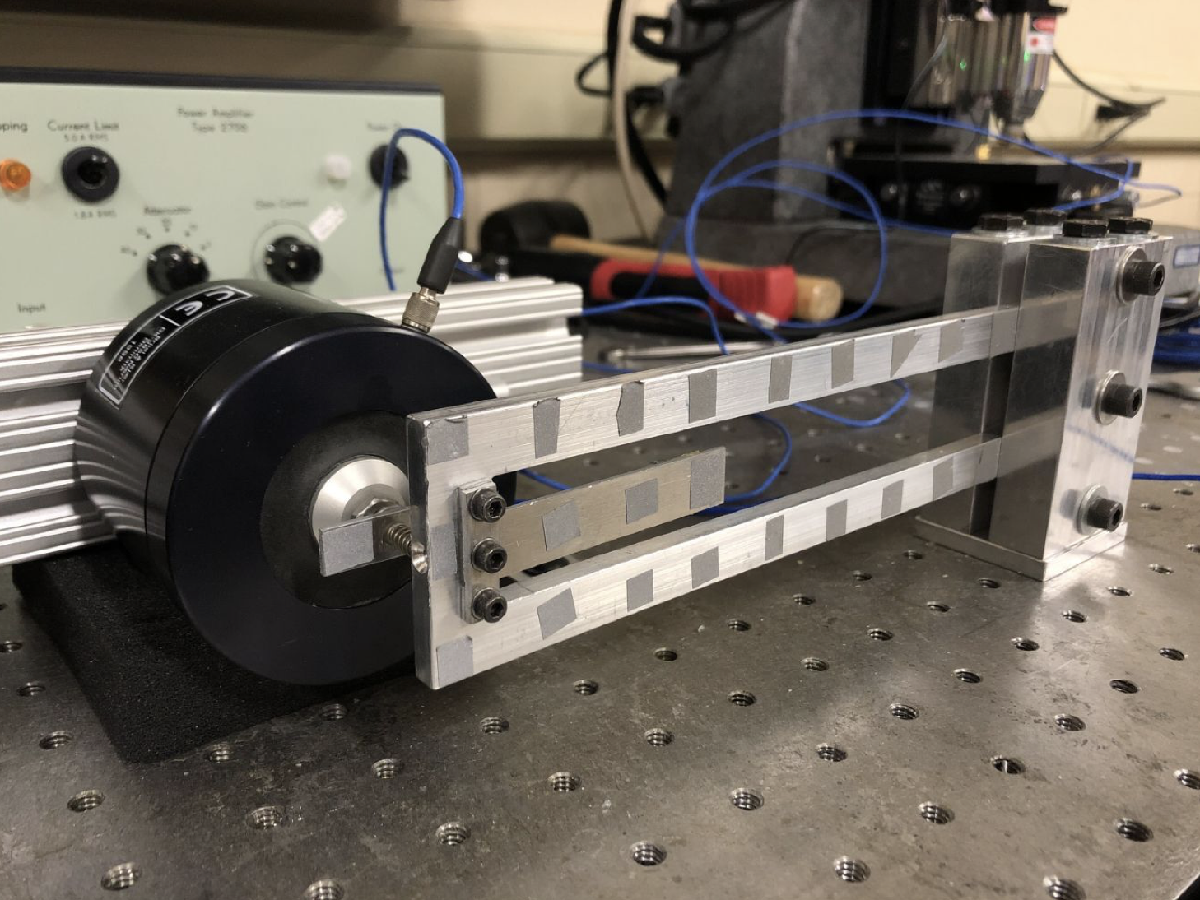

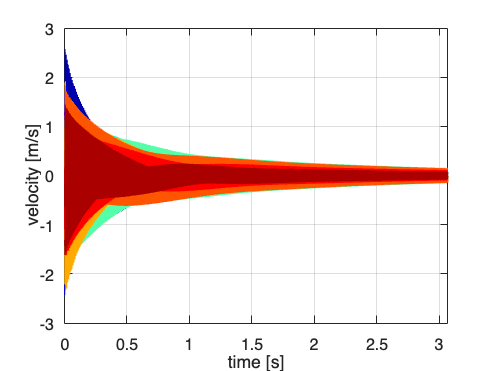

load('data.mat')
% Plot data
customFigure; colororder(jet(size(xData,1)))
for indTraj = 1:size(xData,1)
    plot(xData{indTraj,1},xData{indTraj,2},'Linewidth',1)
end
xlabel('time [s]')
ylabel('velocity [m/s]')
xlim([xData{indTraj,1}(1) xData{indTraj,1}(end)])


% Train and test
indTest = [2 6 10];
indTrain = setdiff(1:size(xData,1),indTest);

Other than time inspection, we also look at time-frequency plots obtained via spectrogram. We can clearly see two frequency components, one which is more excited on some trajectories, less on others.

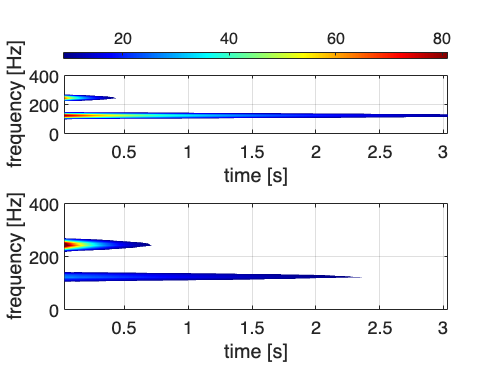

customFigure('subPlot',[2 1]); subplot(211); 
indTraj = 10;
numberWindows = round(length(xData{indTraj,1})/50); 
samplingTime = xData{indTraj,1}(2)-xData{indTraj,1}(1);
[Ss,frequencySpecg,timeSpecg]=spectrogram(xData{indTraj,2}(1,:),numberWindows,round(numberWindows*0.5),[],1/samplingTime);
[timeSpecgGrid,frequencySpecgGrid] = meshgrid(linspace(timeSpecg(1),timeSpecg(end),801),linspace(frequencySpecg(1),frequencySpecg(end),2401));
amplitudeSpecg = interp2(timeSpecg,frequencySpecg,abs(Ss),timeSpecgGrid,frequencySpecgGrid);
amplitudeSpecg(amplitudeSpecg<9) = NaN;
surf(timeSpecgGrid,frequencySpecgGrid,(amplitudeSpecg)); colormap(jet)
ylim([0 400])
xlim([timeSpecg(1) timeSpecg(end)])
xlabel('time [s]')
ylabel('frequency [Hz]')
set(gca,'fontname','helvetica')
set(gca,'fontsize',18)
set(gca,'zscale','log')
colorbar('northoutside')
view(2)
shading interp
climits = caxis;

subplot(212); 
indTraj = 12;
[Ss,frequencySpecg,timeSpecg]=spectrogram(xData{indTraj,2}(1,:),numberWindows,round(numberWindows*0.5),[],1/samplingTime);
[timeSpecgGrid,frequencySpecgGrid] = meshgrid(linspace(timeSpecg(1),timeSpecg(end),801),linspace(frequencySpecg(1),frequencySpecg(end),2401));
amplitudeSpecg = interp2(timeSpecg,frequencySpecg,abs(Ss),timeSpecgGrid,frequencySpecgGrid);
amplitudeSpecg(amplitudeSpecg<9) = NaN;
surf(timeSpecgGrid,frequencySpecgGrid,(amplitudeSpecg)); colormap(jet)
ylim([0 400])
xlim([timeSpecg(1) timeSpecg(end)])
xlabel('time [s]')
ylabel('frequency [Hz]')
set(gca,'fontname','helvetica')
set(gca,'fontsize',18)
set(gca,'zscale','log')
caxis(climits)
view(2)
shading interp

## Delay embedding

Now we arrange the scalar measurements in an observable space of dimension at least $2m+1$, with $m$ the dimension of the manifold. This guarantees that the manifold from the full state space can be embedded in the observable space. We form a multi-dimensional observable by stacking $d$ subsequent scalar measurements $x$ in a vector $y$, and we will later use the trajectories in this augmented space for the manifold fitting.


$$\left[\begin{array}{c}y_{1} \\ \vdots \\ y_{i+1} \\ \vdots \\ y_{d+1}\end{array} 
\right] = \left[\begin{array}{c}x(t^k) \\ \vdots \\ x(t^k+i\Delta t) \\ \vdots 
\\ x(t^k+d\Delta t)\end{array} \right]$$


The total number of embedded coordinates is $2m+1 + \texttt{overEmbed}$. We impose additional delays so that an embedding vector covers 2 pseudo-periods of a slow oscillation.

samplingTime = xData{1,1}(2)-xData{1,1}(1);
slowTime = 1/120; % 1 divided by the (approximate) slow frequency
embeddingTime = 2 * slowTime;
SSMDim = 4;
overEmbed = round(embeddingTime/samplingTime);
[yData, opts_embd] = coordinatesEmbedding(xData, SSMDim, 'OverEmbedding', overEmbed);

The 94 embedding coordinates consist of the measured state and its 93 time-delayed measurements.


## Manifold fitting

The measured trajectories are assumed to lie close to a two-dimensional manifold that is tangent at the origin to the eigenspace corresponding to the slowest pair of eigenvalues. We now want to fit a polynomial of order $M$ to the data points to approximate the manifold. Here we use a graph style parametrization, meaning that the manifold is parametrized using coordinates in the computed eigenspace $V_e$. This excludes the possibility of folds on the manifold (however, if necessary we may circumvent this problem by increasing the dimensionality of the observed space). 

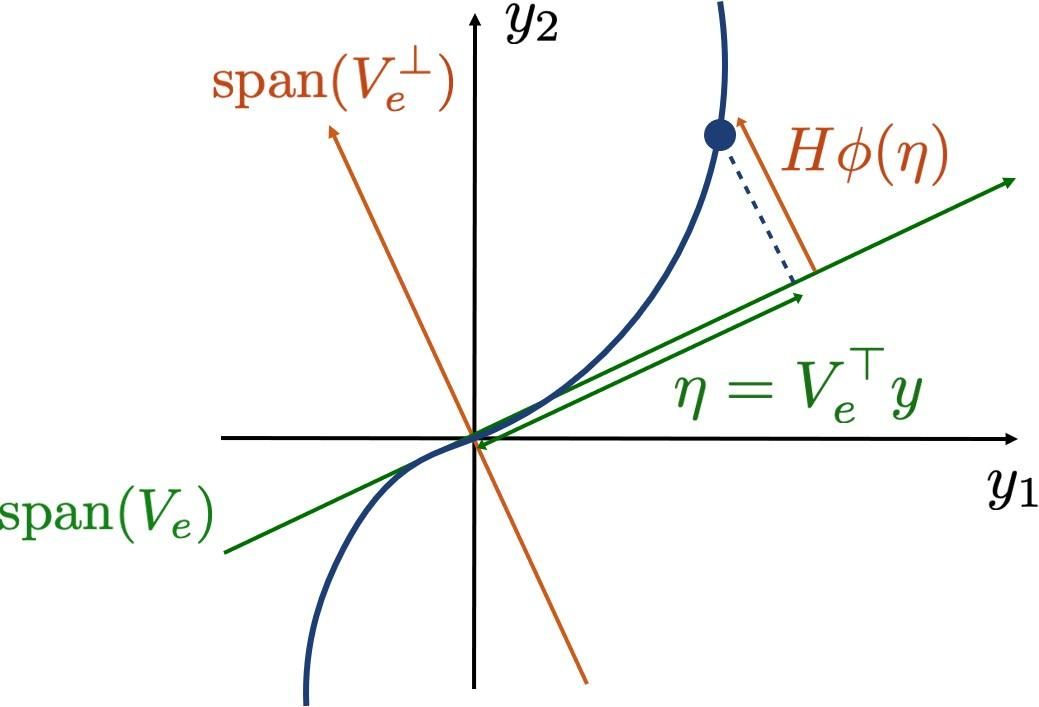

We seek the $2n\times m_M$ polynomial coefficient matrix $H$ of the manifold on the form

$y = V_e V_e^\top y + H \phi_{m,2:M}(V_e^\top y)$,

where the function $\phi_{m,2:M}(q)$ computes a vector of all $m_M$ monomials from orders 2 up to $M$ of an $m$-vector $q$. This optimization problem is formulated as the minimization of a cost function computed from the measured data $y_k$,


$$C_r(V_e,H) = \sum_{k=1}^N ||y_k - V_eV_e^\top y_k - H\phi_{m,2:M}(V_e^\top 
y_k) ||$$


to find $H$ and the $2n\times 2$ eigenspace matrix $V_e$, under the constraints that $V_e^\top H=0$ and $V_e^\top V_e = I$. The minimization is performed with the Matlab function `fmincon` in `IMGeometry`. In this case, we set $M=1$, so that our manifold is the plane spanned by the 4 most relevant directions of the Principal Component Anlysis of data.

SSMOrder = 1;
IMInfo = IMGeometry(yData(indTrain,:), SSMDim, SSMOrder);

## Plot and validation

Now that we have computed the tangent space of the manifold, we pass to the reduced coordinates $y$ by projecting all trajectories onto it:

$\eta = V_e^\top y$.

etaData = projectTrajectories(IMInfo, yData);

We plot the trajectories in the reduced coordinates.

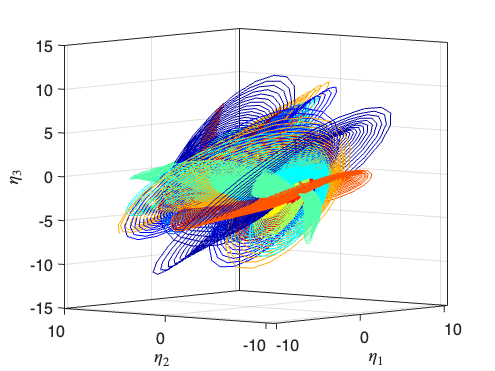

plotReducedCoordinates(etaData);
view(-50,5); legend('off'); colororder(jet(size(xData,1)))

We also compute the static reconstruction error.

normedTrajDist = computeTrajectoryErrors(liftTrajectories(IMInfo,etaData), yData);
staticNMTE = mean(normedTrajDist(indTest))*100 % in percentage

staticNMTE =       0.16515


## Reduced order model

We compute a model for the reduced dynamics with the training data projected onto the manifold. The function `IMDynamicsFlow` fits a polynomial map


$$\dot{\eta} = W_r \phi(\eta)$$


where $\phi(\eta)$ again computes a vector of all monomials of $\eta$, and $W_r$ is a matrix of polynomial coefficients. 

We are also specifying that we want the reduced dynamics on a normal form, and seek the Taylor expansion of a map $N$ fulfilling


$$\dot{z} = N(z) =Dz + W_n\phi(z)$$


with $D$ a diagonal matrix and $W_n$ containing coefficients for the near-resonant nonlinear terms, after a near-identity change of coordinates


$$z = T^{-1}(\eta) = \eta + W_t \phi(\eta)$$


with $W_t$ containing the coefficients for the nonlinear terms of the coordinate change. We feed the algorithm with the specification of the ratio of the resonant frequencies to facilitate the recognition of the normal form.

Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1          0.27056                          6.19
     1           4         0.134393     0.00268634           8.63  
     2           6         0.121096       0.181728           2.83  
     3           7         0.108353              1           7.32  
     4           9        0.0985289       0.350751           1.73  
     5          10        0.0909289              1           1.01  
     6          11        0.0849516              1          0.955  
     7          12        0.0742036              1          0.777  
     8          13        0.0687933              1          0.898  
     9          14        0.0607143              1           2.18  
    10          16        0.0579362       0.223347           2.94  
    11          17

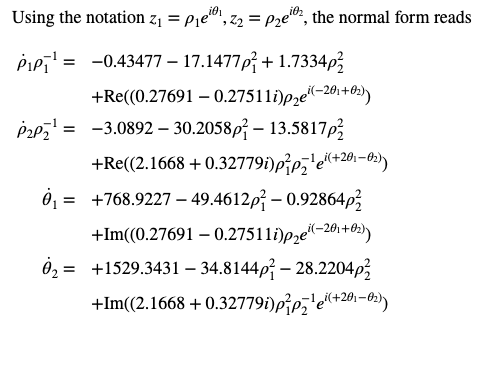

ROMOrder = 3;
RDInfo = IMDynamicsFlow(etaData(indTrain,:), ...
    'R_PolyOrd', ROMOrder, 'style', 'normalform','frequencies_norm',[1 2],'IC_nf',1,'MaxIter',3e3);

frequenciesHz = imag(RDInfo.eigenvaluesLinPartFlow(1:2))/2/pi

frequenciesHz =        122.38
        243.4


We transform the initial condition of our test trajectories according to the obtained change of coordinates, and integrate our reduced order evolution rule to predict the development of the trajectory. 

[yRec, etaRec, zRec] = advect(IMInfo, RDInfo, yData);

## Evaluation

The error NMTE is computed as the average distance of the predicted trajectory to the measured one in the full observable.

fullTrajDist = computeTrajectoryErrors(yRec, yData);
NMTE = mean(fullTrajDist(indTest))*100 % in percentage

NMTE =        3.6498


We plot the measured and predicted signal for the test trajectories. 

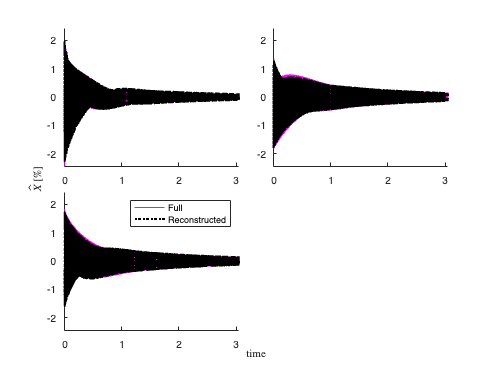

plotTrajectories(yData(indTest,:), yRec(indTest,:), 'm', 1)
ylabel('$\hat{X} \, [\%]$','Interpreter','latex'); title('');

## Decays along the SSM and instantaneous damping

We plot the trajectories decay on the $(\rho_1,\rho_2)$ plane, splitting hence the slow and fast directions.

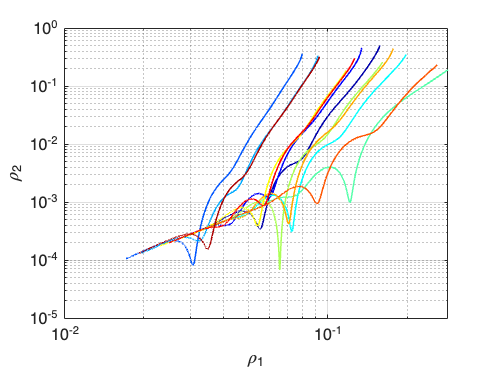

customFigure; colororder(jet(size(xData,1)))
for indTraj = 1:size(xData,1)
    plot(abs(zRec{indTraj,2}(1,:)),abs(zRec{indTraj,2}(2,:)),'Linewidth',1.5)
end
xlabel('\rho_1')
ylabel('\rho_2')
set(gca,'xscale','log')
set(gca,'yscale','log')

We now focus on the decaying trajectories excited from the third impact position. First, we display the relative modal energy content over time:

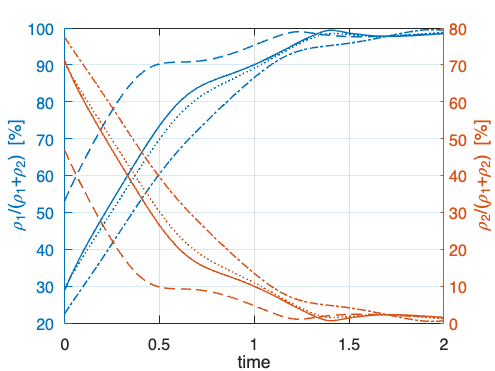

customFigure; 
for indTraj = 9:size(xData,1)
    instEnergy = abs(zRec{indTraj,2}(1,:))+abs(zRec{indTraj,2}(2,:));
    yyaxis left
    plot(zRec{indTraj,1},abs(zRec{indTraj,2}(1,:))./instEnergy*100,'Linewidth',1.5)
    yyaxis right
    plot(zRec{indTraj,1},abs(zRec{indTraj,2}(2,:))./instEnergy*100,'Linewidth',1.5)
end
xlim([0 2])
xlabel('time')
yyaxis left
ylabel('\rho_1/(\rho_1+\rho_2) [%]')
yyaxis right
ylabel('\rho_2/(\rho_1+\rho_2) [%]')

and then we show the instantaneous damping evolution. Instantaneous damping is already a function handle present in the normal form reduced dynamics, so one just needs to be evaluated it and plot the results.

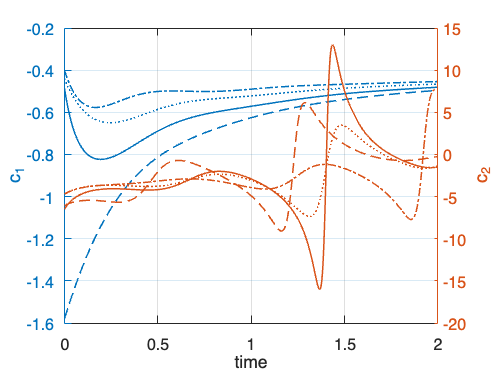

customFigure; 
for indTraj = 9:size(xData,1)
    instDamping = RDInfo.conjugateDynamics.damping(abs(zRec{indTraj,2}(1:2,:)),atan2(imag(zRec{indTraj,2}(1:2,:)),real(zRec{indTraj,2}(1:2,:))));    
    yyaxis left
    plot(zRec{indTraj,1},instDamping(1,:),'Linewidth',1.5)
    yyaxis right
    plot(zRec{indTraj,1},instDamping(2,:),'Linewidth',1.5)
end
xlim([0 2])
xlabel('time')
yyaxis left
ylabel('c_1')
yyaxis right
ylabel('c_2')